dhparams = [0  -pi/2	8   	0;
           0	pi/4     80   0;
          0	pi/2	135	0;
            0   -pi/4	147	0;
            0   pi/2	30   	0;
           0      0      40    0];

robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','fix');

setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')
  
%Create and add other rigid bodies to the robot. 
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','fix');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','fix');

setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');
setFixedTransform(jnt6,dhparams(6,:),'dh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')

showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1        fixed             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5        fixed            body4(4)   body6(6)  
   6        body6         jnt6        fixed            body5(5)   
--------------------


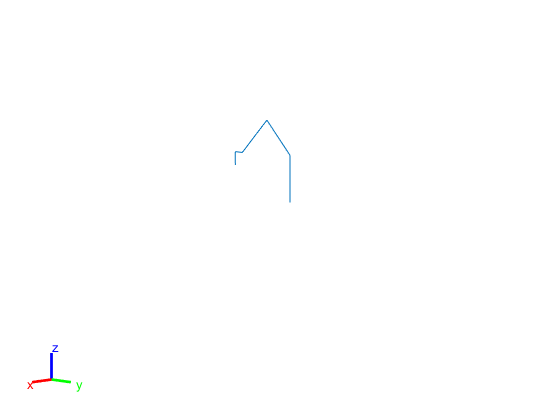

show(robot);
axis([-300,300,-300,300,-300,300])
axis off

robot.DataFormat = 'row';
%Set the Gravity property to give a specific gravitational acceleration.

robot.Gravity = [0 0 -9.81];
%Generate a random configuration for lbr.

q = randomConfiguration(robot);
%Compute the required joint torques for lbr to statically hold that configuration.

tau = inverseDynamics(robot,q);

initTargetPose=;

表达式无效。请检查缺失或多余的字符。

q0=;
scale=;